Projekt: pole elektryczne wokół naładowanego koła

Daniel Kawecki, Mateusz Starczyk, Ignacy Żywalewski

Parametry układu

% zakres osi 
x1 = -10;
x2 = 10;
y1 = -10;
y2 = 10;

% liczba punktów na jaką dzielimy koło
n = 100;

% promień koła
r = 9;

% pozycja
position = [0, 0];

% całkowity ładunek stałej gęstości powierzchniowej σ
charge = 10e-9;

% stała elektrostatyczna
k = 9e9;

Podział koła

% powierzchnia pojedyńczego punktu
point_area = (x2-x1)/(n-1) * (y2-y1)/(n-1);

% pole koła
area = pi*r^2;

% obliczenie ile punktów zmieści się w kole
number_of_points = area/point_area;

% obliczenie ładunku pojedyńczego punktu
point_charge = charge/number_of_points;

Stworzenie koła

% siatka
[X, Y] = meshgrid(linspace(x1, x2, n), linspace(y1, y2, n));

% wzór na koło
Z = (X-position(1)).^2 + (Y-position(2)).^2 - r^2;

% normalizacja
Z = abs(Z)./Z;

% transformacja żeby wnętrze koła było równe 1, a to co na zewnątrz równe 0
Z = (-Z+1)/2;

% wysokość koła ustawiamy na równą wartości pojedyńczego ładunku
Z = Z*point_charge;

Zadanie 1.

Oblicznie natężenia pola elektrycznego 

% inicjalizacja tablic 
E_x_total = zeros(n, n);
E_y_total = zeros(n, n);
V_x_total = zeros(n, n);
V_y_total = zeros(n, n);

for i = 1:numel(Z) % pętla przechodząca przez wszystkie puntky siatki
  % jeżeli punkt nie znajduje się w kółku to wykonujemy obliczenia. Punkty
  % w środku kółka nas nie iteresują więc je pomijamy
  if Z(i) == 0 

    % obecny punkt
    point = [X(i), Y(i)];

    % odległość pomiędzy obecnym punktem, a resztą punktów
    r_x = X-point(1);
    r_y = Y-point(2);

    % prawdziwa odległość pomiędzy obecnym punktem, a resztą punktów
    r_c = sqrt((r_x.^2 + r_y.^2));

    %
    %  obliczanie natężenia pola elektrycznego
    %

    % siła pola elektrycznego wytwarzanego przez ten punkt (lokalizacja w tablicy)
    % w bieżącym punkcie (ten powyżej)
    E_x = (k * Z .* r_x ./ r_c.^3);
    E_y = (k * Z .* r_y ./ r_c.^3);

    % punkt nie oddziałuje na samego siebie i we wzorze w tym miejscu powstaje
    % dzielenie przez 0 do produkuje NaNa którego się pozbywamy
    E_x(i) = 0;
    E_y(i) = 0;

    % sumujemy wyniki wszystkich pól elektrycznych i otrzymujemy końcowe
    % pole elektryczne działające na bieżący punkt
    E_x_total(i) = sum(E_x(:));
    E_y_total(i) = sum(E_y(:));

    %
    %  obliczanie potencjału pola elektrycznego
    %

    % potencjał wytwarzony przez punkty na bierzoącym punkcie
    V_x = (k * Z .* r_x ./ r_c.^2);
    V_y = (k * Z .* r_y ./ r_c.^2);

    % wzór wytwarza dzielenie przez 0 w tym punkcie w ktorym sie znajduje
    % co wytwarza NaNa którego się pozbywamy
    V_x(i) = 0;
    V_y(i) = 0;

    % sumujemy wartości wszsytkich potencjałów pól i otrzymujemy końcowe
    % natężenie w bieżącym punkcie
    V_x_total(i) = sum(V_x(:));
    V_y_total(i) = sum(V_y(:));

  else
    % aby na wykresach wartości punktów w środku kółka nie były wyświetlane
    % ustawiamy ich wartość na NaN który nie jest wyświetlany na wykresach
    E_x_total(i) = NaN;
    E_y_total(i) = NaN;

    V_x_total(i) = NaN;
    V_y_total(i) = NaN;
  end

end

% sumujemy pole działające w kierunkach x i y natężenia pola elektrycznego
E_total = sqrt(E_x_total.^2 + E_y_total.^2);
V_total = sqrt(V_x_total.^2 + V_y_total.^2);

Wyresy natężenia pola elektrycznego

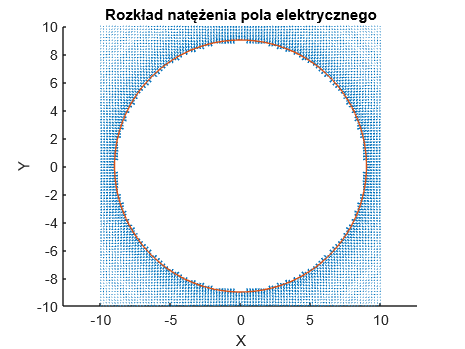

% generowanie koła
theta = linspace(0,2*pi);
x = r*cos(theta);
y = r*sin(theta);

% wykres kierunków natężenia pola
figure;
hold on;
quiver(X, Y, E_x_total, E_y_total)
title('Rozkład natężenia pola elektrycznego')
xlabel("X")
ylabel('Y')
plot(x,y)
hold off;

axis([-10 10 -10 10])
axis equal

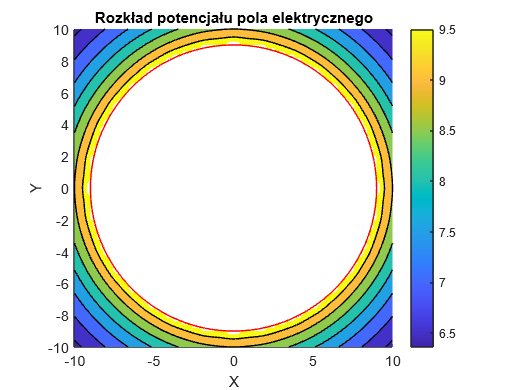


% wykres potencjału
figure;
hold on
contourf(X, Y, V_total);
colorbar
title("Rozkład potencjału pola elektrycznego")
xlabel("X")
ylabel("Y")
plot(x,y,'r')
hold off

axis([-10 10 -10 10])
axis equal

Zadanie 2.

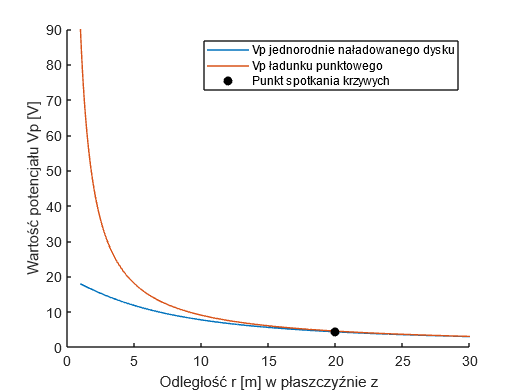

close all;

% Promień koła
r = 9;

% Całościowy ładunek q
charge = 10e-9;

% Powierzchnia koła (dysku)
area = pi*r^2;

% Stała elektrostatyczna
k = 9*10^9;

% Przedział z, dla którego obliczamy potencjał
z = linspace(1, 30, 1000);

% Powierzchniowa gęstość ładunku (mała sigma)
surface_charge_density = charge/area;

% Potencjał w odległości z dla ładunku punktowego
V = (k*charge)./z;

% Potencjał w odległości z dla jednorodnie naładowanego dysku
Vp = k*2*pi*surface_charge_density*(sqrt((z.^2)+(r^2))-sqrt(z.^2));

% Wykres
figure
hold on
plot(z, Vp)
plot(z, V)
scatter(20, k*charge/20, MarkerFaceColor='black', MarkerEdgeColor='black', Marker='o')
hold off

% Legenda wykresu
%title('')
xlabel('Odległość r [m] w płaszczyźnie z')
ylabel('Wartość potencjału Vp [V]')
legend('Vp jednorodnie naładowanego dysku', 'Vp ładunku punktowego', 'Punkt spotkania krzywych')


% Mniej więcej dla odległości 20 metrów można uznać taki dysk za ładunek punktowy